# Tutorial 11 - Simulate a LNMO-Graphite MLP Cell

## Introduction

In this tutorial, we simulate a multilayer pouch cell. We use the same material property as in the other tutorials

jsonfilename = fullfile('ParameterData', 'BatteryCellParameters', 'LithiumIonBatteryCell', ...
                        'lithium_ion_battery_lnmo_graphite.json');
jsonstruct_material = parseBattmoJson(jsonfilename);

Next, we load and parse a json file where we have chosen some parameters for the multilayer pouch domain. Note that all the parameters are described in a json schema, see [Geometry.schema.json](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/JsonSchemas/Geometry.schema.json), even if the simplest way to proceed is to start with an example, in this case given by [geometryMultiLayerPouch.json](https://github.com/BattMoTeam/BattMo/blob/main/Examples/JsonDataFiles/geometryMultiLayerPouch.json).

jsonfilename = 'Examples/JsonDataFiles/geometryPX90300.json';
jsonstruct_geometry = parseBattmoJson(jsonfilename);

We use [FlatJsonViewer.m](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/JsonUtils/FlatJsonViewer.m) to flatten the json structure and print it to screen. We can see that, in this example, we use 5 layers and two different lengths for the tabs (height value). At the moment, the two tabs share the same width. Implementing a separate width for each tab would require to modify the grid generator for this geometry. It is more a developper work but is definitely not out of reach.

fjv = flattenJson(jsonstruct_geometry)

fjv =   FlatJsonViewer with properties:

       flatjson: {23×2 cell}
    columnnames: {'parameter name'  'parameter value'}


fjv.print();

T = 23×2 table
                     parameter name                       parameter value  
    ________________________________________________    ___________________

    {'Geometry.case'                               }    {'multiLayerPouch'}
    {'Geometry.nLayers'                            }    {[              5]}
    {'Geometry.width'                              }    {[         0.0990]}
    {'Geometry.length'                             }    {[         0.3000]}
    {'Geometry.tab.width'                          }    {[         0.0450]}
    {'Geometry.tab.Nx'                             }    {[              3]}
    {'Geometry.tab.NegativeElectrode.length'       }    {[         0.0225]}
    {'Geometry.tab.NegativeElectrode.Ny'           }    {[              2]}
    {'Geometry.tab.PositiveElectrode.length'       }    {[         0.0225]}
    {'Geometry.tab.PositiveElectrode.Ny'           }    {[              2]}
    

We load and parse the control protocol

jsonfilename = fullfile('Examples', 'JsonDataFiles', 'cc_discharge_control.json');
jsonstruct_control = parseBattmoJson(jsonfilename);

jsonstruct_control.Control.lowerCutoffVoltage = 4;
% jsonstruct_control.Control.upperCutoffVoltage = 4.8;
% jsonstruct_control.Control.dIdtLimit = 1e-4;
% jsonstruct_control.Control.dEdtLimit = 1;

We load and parse the simulation settings. This is optional. Typically, reasonable choices are made by default.

%jsonfilename = fullfile('Examples', 'jsondatafiles', 'simulation_parameters.json');
%jsonstruct_simparams = parseBattmoJson(jsonfilename);

Now, we can merge these parameter definitions into a single parameter set to obtain a jsonstruct that has all the input needed by the simulator.

jsonstruct = mergeJsonStructs({jsonstruct_geometry , ...
    jsonstruct_material , ...
    jsonstruct_control  }, 'warn', false);

## Setup the model for inspection

When we run the simulation using function [runBatteryJson.m](https://github.com/BattMoTeam/BattMo/blob/main/Examples/JsonInput/runBatteryJson.m), the model is setup. In the case where we want to setup the model for inspection, prior to simulation, we can use the function [setupModelFromJson.m](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/JsonUtils/setupModelFromJson.m)

model = setupModelFromJson(jsonstruct);

css = CellSpecificationSummary(model);
css = css.updatePackingMass(30*gram);
css.printSpecifications();

               Packing mass : 0.03     kg
                Temperature : 24.85    C
                       Mass : 0.131967 kg
                     Volume : 0.0392769 L
             Total Capacity : 5.93465  Ah
Negative Electrode Capacity : 7.85507  Ah
Positive Electrode Capacity : 5.93465  Ah
                  N/P ratio : 1.32359  -
                     Energy : 27.3354  Wh
            Specific Energy : 207.137  Wh/kg
             Energy Density : 695.966  Wh/L
            Initial Voltage : 4.82663  V


We use the [plotBatteryGrid.m](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/Visualization/plotBatteryGrid.m) function to show the grid

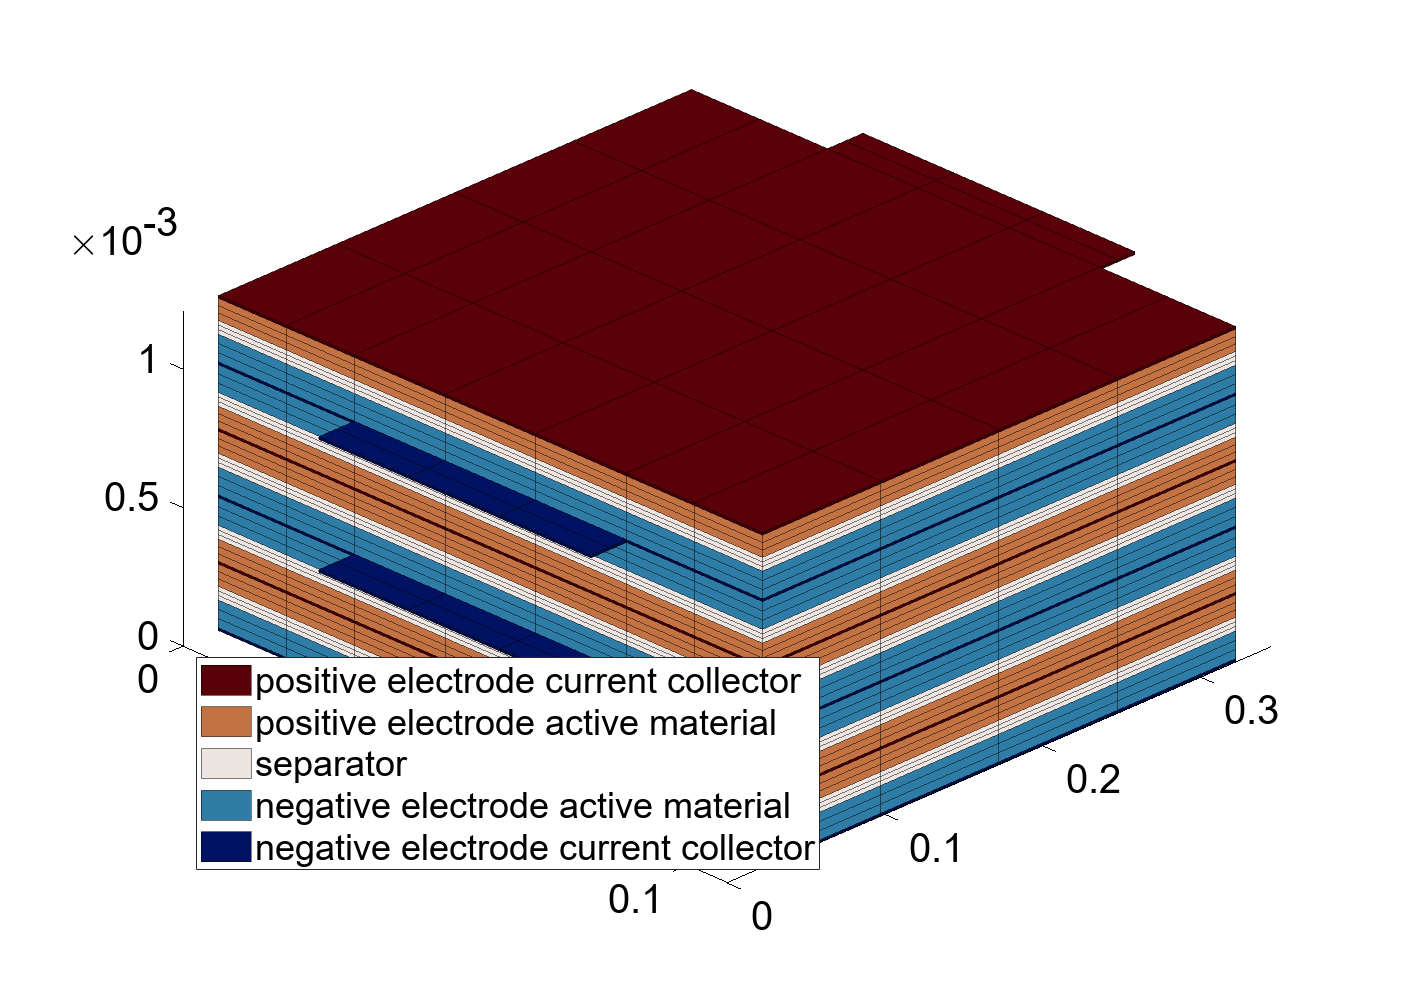

plotBatteryGrid(model)
% make the axis tight and set the camera viewing angle
axis tight
view(45,45)

## Run the simulation

warning off
output = runBatteryJson(jsonstruct);

Solving timestep 001/100:                                            -> 50 Seconds, 399 Milliseconds
Solving timestep 002/100: 50 Seconds, 399 Milliseconds               -> 100 Seconds, 799 Milliseconds
Solving timestep 003/100: 100 Seconds, 799 Milliseconds              -> 151 Seconds, 199 Milliseconds
Solving timestep 004/100: 151 Seconds, 199 Milliseconds              -> 201 Seconds, 599 Milliseconds
Solving timestep 005/100: 201 Seconds, 599 Milliseconds              -> 252 Seconds
Solving timestep 006/100: 252 Seconds                                -> 302 Seconds, 399 Milliseconds
Solving timestep 007/100: 302 Seconds, 399 Milliseconds              -> 352 Seconds, 799 Milliseconds
Solving timestep 008/100: 352 Seconds, 799 Milliseconds              -> 403 Seconds, 199 Milliseconds
Solving timestep 009/100: 403 Seconds, 199 Milliseconds              -> 453 Seconds, 599 Milliseconds
Solving timestep 010/100: 453 Seconds, 599 Milliseconds              -> 503 Seconds, 999 Milliseconds

## Visualize the Results

extract the time and voltage quantities

states = output.states;

time    = cellfun(@(state) state.time, states);
voltage = cellfun(@(state) state.('Control').E, states);

We plot the discharge curves together in a new figure

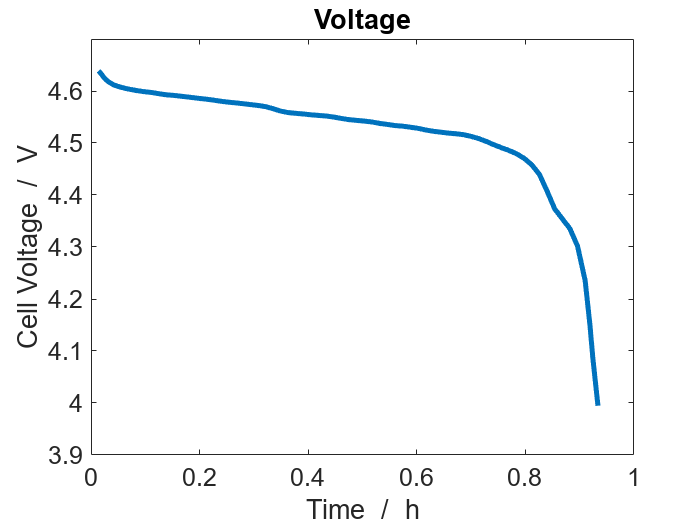

figure();
plot((time/hour), voltage, '-', 'linewidth', 3)
xlabel('Time  /  h')
ylabel('Cell Voltage  /  V')
title('Voltage');

We plot the minimum and maximum values of the temperature in the model as a function of time. The temperature for each grid cell, is stored in `state.ThermalModel.T`. For each computed step, we extract the minimum and maximum value of the temperature

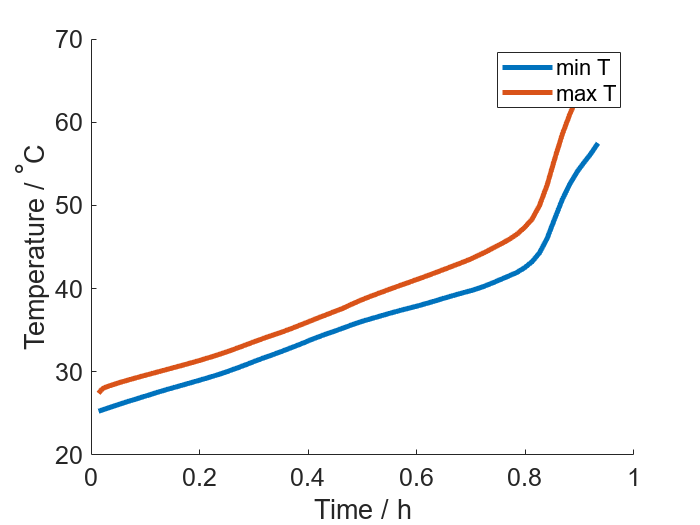

T0 = PhysicalConstants.absoluteTemperature;

states = output.states;
Tmin = cellfun(@(state) min(state.ThermalModel.T + T0), states);
Tmax = cellfun(@(state) max(state.ThermalModel.T + T0), states);

figure
hold on
plot(time / hour, Tmin, 'displayname', 'min T', 'LineWidth', 3);
plot(time / hour, Tmax, 'displayname', 'max T', 'LineWidth', 3);
xlabel('Time / h');
ylabel('Temperature / ^{\circ}C');

legend show

## Temperature distribution at final time

We have access to the temperature distribution for all the time steps. Here, we plot the temperature on the 3D model. We find a extensive set of plotting functions in [MRST](https://www.sintef.no/Projectweb/MRST/). You may be interested to have a look at the [Visualization Tutorial](https://www.sintef.no/projectweb/mrst/documentation/tutorials/visualization-tutorial/). We use [plotCellData](https://github.com/SINTEF-AppliedCompSci/MRST/blob/main/core/plotting/plotCellData.m) to plot the temperature. The function [plotToolbar.m](https://github.com/SINTEF-AppliedCompSci/MRST/blob/main/visualization/mrst-gui/plotToolbar.m) is also convenient to visualize values inside the domain in a interactive way.

state = states{end}

state = struct with fields:
          Electrolyte: [1×1 struct]
    NegativeElectrode: [1×1 struct]
    PositiveElectrode: [1×1 struct]
         ThermalModel: [1×1 struct]
              Control: [1×1 struct]
                 time: 3.3611e+03


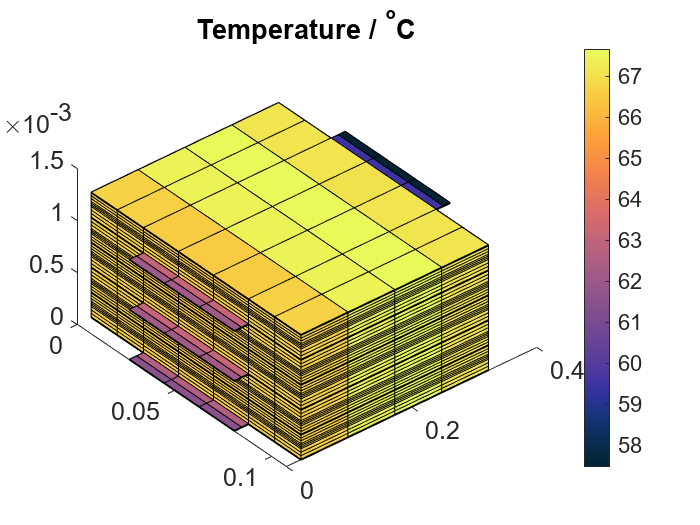

figure
plotCellData(model.ThermalModel.grid, ...
    state.ThermalModel.T + T0);
colormap(cmocean('thermal'));
colorbar
title('Temperature / ^{\circ}C');
view([50, 50]);

For a given time step, we plot the concentration on the grid.

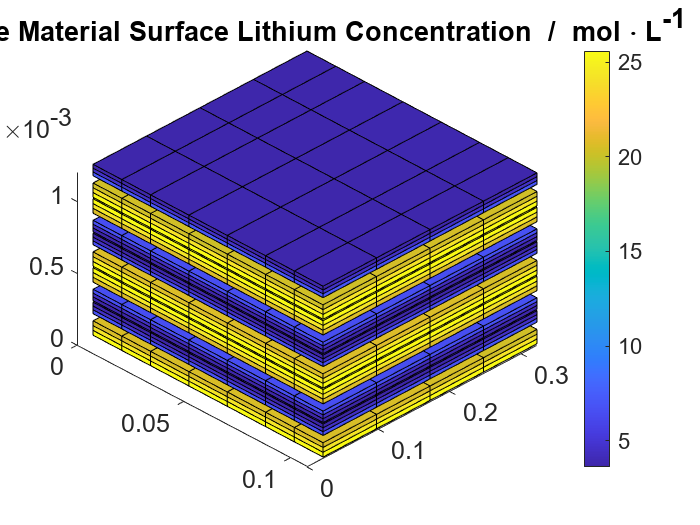

% Set the timestep we want to visualize
timestep = 20;

% get the state of the simulation at the given timestep
state = states{timestep};

% create a new figure
figure()

% plot the surface concentration of lithium in the negative electrode active material
plotCellData(model.NegativeElectrode.Coating.grid, state.NegativeElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface/(mol/litre))

% plot the surface concentration of lithium in the positive electrode active material
plotCellData(model.PositiveElectrode.Coating.grid, state.PositiveElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface/(mol/litre))

title('Active Material Surface Lithium Concentration  /  mol \cdot L^{-1}');
% add a colorbar
colorbar()
view(45,45)